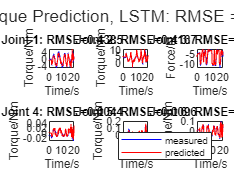

clc;
clear;

data = 'free_space';
contact = 'no_contact';
test_folder = 'test';
rnn = 'lstm';
network = '_seal_pred_filtered_torque_si.csv';

%loss = 0;
loss = [0,0,0,0];

%for file = 0:3
file = 0;
exp = ['exp',num2str(file)];

if strcmp(test_folder, 'test')
%     joint_path = ['../../data_2_23/csv_si/', test_folder, '/', data, '/joints/'];
%     torque_path = ['../../data_2_23/csv_si/', test_folder, '/', data, '/', 'attn', network];
    
      joint_path = ['data_2_23/csv_si/', test_folder, '/', data, '/joints/'];
      torque_path = ['data_2_23/csv_si/', test_folder, '/', data, '/', 'lstm', network];
else
    joint_path = ['../../dvrk-si-3-15/csv_si/', test_folder, '/', data, '/joints/'];
    torque_path = ['../../dvrk-si-3-15/csv_si/', test_folder, '/', data, '/', 'ff', network];
end

joint_data = readmatrix([joint_path, 'interpolated_all_joints.csv']);
torque_data = readmatrix(torque_path);

%%%%%%%%%%%%%%% apply filter
% windowSize = 100; 
% b = (1/windowSize)*ones(1,windowSize);
% a = 1;
% 
% joint_data = filter(b,a,joint_data);

measured_torque = joint_data(:,14:16);
fs_pred_torque = torque_data(:,2:4);

%%%%%%%%%%%%%%% cut the first 30%
fs_pred_torque = fs_pred_torque(1:length(fs_pred_torque)*0.1, :);
joint_data = joint_data(1:length(fs_pred_torque), :);
torque_data = torque_data(1:length(fs_pred_torque), :);




loss(file+1) = mean(sqrt(mean((joint_data(1:length(fs_pred_torque),14:19) - torque_data(:,2:7)).^2)));

loss1 = mean(sqrt(mean((measured_torque(1:length(fs_pred_torque),1) - fs_pred_torque(:,1)).^2)));
loss2 = mean(sqrt(mean((measured_torque(1:length(fs_pred_torque),2) - fs_pred_torque(:,2)).^2)));
loss3 = mean(sqrt(mean((measured_torque(1:length(fs_pred_torque),3) - fs_pred_torque(:,3)).^2)));

loss_joint1 = mean(sqrt(mean((joint_data(1:length(fs_pred_torque),14) - torque_data(:,2)).^2)));
loss_joint2 = mean(sqrt(mean((joint_data(1:length(fs_pred_torque),15) - torque_data(:,3)).^2)));
loss_joint3 = mean(sqrt(mean((joint_data(1:length(fs_pred_torque),16) - torque_data(:,4)).^2)));
loss_joint4 = mean(sqrt(mean((joint_data(1:length(fs_pred_torque),17) - torque_data(:,5)).^2)));
loss_joint5 = mean(sqrt(mean((joint_data(1:length(fs_pred_torque),18) - torque_data(:,6)).^2)));
loss_joint6 = mean(sqrt(mean((joint_data(1:length(fs_pred_torque),19) - torque_data(:,7)).^2)));

figure()
tcl = tiledlayout(2,3,'TileSpacing','Compact','Padding','Compact');

% title(tcl, sprintf('LSTM %s: RMSE = %.4f', test_folder, loss(1)))
title(tcl, sprintf('Torque Prediction, LSTM: RMSE = %.4f', loss(1)))


nexttile
plot(joint_data(:, 1)-joint_data(1,1), joint_data(:,14), 'b')
hold on
title(sprintf('Joint 1: RMSE=%.4f', loss_joint1))
plot(torque_data(:, 1), torque_data(:,2), 'r')
xlabel('Time/s')
ylabel('Torque/Nm')

nexttile
plot(joint_data(:, 1)-joint_data(1,1), joint_data(:,15), 'b')
hold on
title(sprintf('Joint 2: RMSE=%.4f', loss_joint2))
plot(torque_data(:, 1), torque_data(:,3), 'r')
xlabel('Time/s')
ylabel('Torque/Nm')

nexttile
plot(joint_data(:, 1)-joint_data(1,1), joint_data(:,16), 'b')
hold on
title(sprintf('Joint 3: RMSE=%.4f', loss_joint3))
plot(torque_data(:, 1), torque_data(:,4), 'r')
xlabel('Time/s')
ylabel('Force/N')

nexttile
plot(joint_data(:, 1)-joint_data(1,1), joint_data(:,17), 'b')
hold on
title(sprintf('Joint 4: RMSE=%.4f', loss_joint4))
plot(torque_data(:, 1), torque_data(:,5), 'r')
xlabel('Time/s')
ylabel('Torque/Nm')

nexttile
plot(joint_data(:, 1)-joint_data(1,1), joint_data(:,18), 'b')
hold on
title(sprintf('Joint 5: RMSE=%.4f', loss_joint5))
plot(torque_data(:, 1), torque_data(:,6), 'r')
xlabel('Time/s')
ylabel('Torque/Nm')

nexttile
plot(joint_data(:, 1)-joint_data(1,1), joint_data(:,19), 'b')
hold on
title(sprintf('Joint 6: RMSE=%.4f', loss_joint6))
plot(torque_data(:, 1), torque_data(:,7), 'r')
xlabel('Time/s')
ylabel('Torque/Nm')
legend('measured', 'predicted')




% subplot(2,3,1)
% plot(joint_data(:, 1)-joint_data(1,1), joint_data(:,14), 'b')
% title(data)
% hold on
% plot(torque_data(:, 1), torque_data(:,2), 'r')
% legend('measured', 'predicted')
% title(data)
% hold off
% subplot(2,3,2)
% plot(joint_data(:, 1)-joint_data(1,1), joint_data(:,15), 'b')
% title(data)
% hold on
% plot(torque_data(:, 1), torque_data(:,3), 'r')
% legend('measured', 'predicted')
% title('Torque')
% hold off
% subplot(2,3,3)
% plot(joint_data(:, 1)-joint_data(1,1), joint_data(:,16), 'b')
% title(data)
% hold on
% plot(torque_data(:, 1), torque_data(:,4), 'r')
% legend('measured', 'predicted')
% title('Torque')
% hold off
% subplot(2,3,4)
% plot(joint_data(:, 1)-joint_data(1,1), joint_data(:,17), 'b')
% title(data)
% hold on
% plot(torque_data(:, 1), torque_data(:,5), 'r')
% legend('measured', 'predicted')
% title('Torque')
% hold off
% subplot(2,3,5)
% plot(joint_data(:, 1)-joint_data(1,1), joint_data(:,18), 'b')
% title(data)
% hold on
% plot(torque_data(:, 1), torque_data(:,6), 'r')
% legend('measured', 'predicted')
% title('Torque')
% hold off
% subplot(2,3,6)
% plot(joint_data(:, 1)-joint_data(1,1), joint_data(:,19), 'b')
% title(data)
% hold on
% plot(torque_data(:, 1), torque_data(:,7), 'r')
% legend('measured', 'predicted')
% title('Torque')
% hold off
%end


